# Filtros

## Importar datos

Importar "S9_Filtros.mat" de Utils4SP

load("..\..\Utils4SP\Datasets\S9_Filtros.mat")

% Preprocesamiento de datos:
atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"])=fillmissing(atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"]),"linear");

## Promedio Móvil: "quita oscilaciones de alta frecuencia"

- Aplicar promedio móvil a todos los campos de atmósfera

- Comparar series de tiempo antes y después.

- Comparar el contenido espectral antes y después del filtro.

- Hacer un chart de dispersión y hacer nuevamente un ajuste. Comparar la calidad de los ajustes respecto a la práctica de S5.

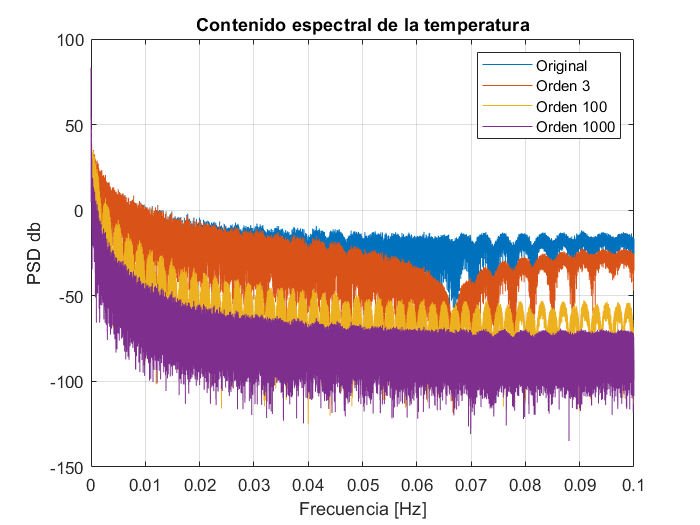

%Promedio Móvil
% Primero aplicamos el promedio móvil a varios campos de "atmosfera"
% hacemos un promedio móvil tomando 3, 100 y 1000 puntos a los lados
atmos_movMean_3 = movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},3);
atmos_movMean_100 = movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},100);
atmos_movMean_1000 = movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},1000);

%Visualizar temperatura sin filtro y con filtros:
plot(atmosfera.DateTime, [ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)], 'LineWidth',2)
xlim([datetime(2021,05,19) datetime(2021,05,20)])
legend("Original", "Orden 3", "Orden 100", "Orden 1000")
ylabel("Temperatura °C")
title("Temperatura en casa de Aldo")

%Contenido espectral:
N = numel(atmosfera.Temp_C);
[Pxx,f] = periodogram([ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],flattopwin(N),N*10,1/5);

% Ploteamos el espectrograma
figure
plot(f,pow2db(Pxx))
legend("Original", "Orden 3", "Orden 100", "Orden 1000")
title("Contenido espectral de la temperatura")
ylabel("PSD db")
xlabel("Frecuencia [Hz]")
grid on

%Ajuste(porque se ve fea la siguiente gráfica de scatter)

[fit_line_nofil,gof] = fit(atmosfera.Temp_C,atmosfera.Hum_perc,'poly2')

fit_line_nofil =      Linear model Poly2:
     fit_line_nofil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.05092  (0.05045, 0.05139)
       p2 =      -5.293  (-5.319, -5.266)
       p3 =       142.2  (141.8, 142.5)

gof = struct with fields:
           sse: 1.4789e+07
       rsquare: 0.7424
           dfe: 137519
    adjrsquare: 0.7424
          rmse: 10.3702


[fit_line_fil,gof] = fit(atmos_movMean_1000(:,2),atmos_movMean_1000(:,3),'poly2')

fit_line_fil =      Linear model Poly2:
     fit_line_fil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.07618  (0.07451, 0.07785)
       p2 =      -6.507  (-6.589, -6.426)
       p3 =       156.1  (155.1, 157)

gof = struct with fields:
           sse: 1.4673e+07
       rsquare: 0.7367
           dfe: 137519
    adjrsquare: 0.7367
          rmse: 10.3294


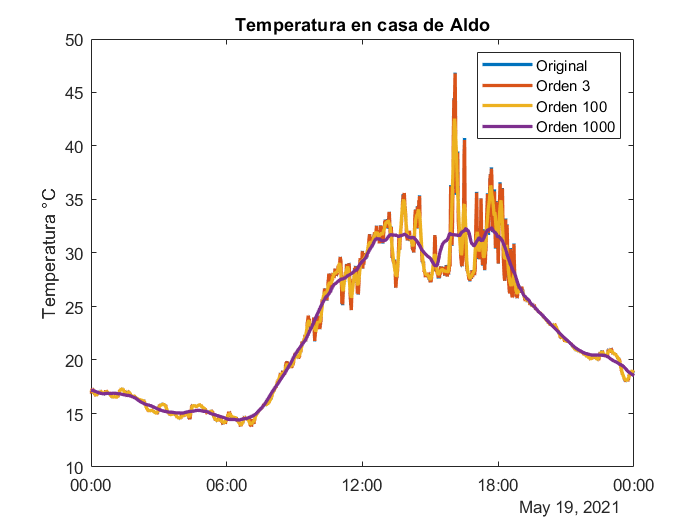


%Dispersión filtrada Humedad vs temperatura

%Plot original
figure
scatter(atmosfera.Temp_C,atmosfera.Hum_perc)
hold on

%plot del ajuste para datos originales
plot(fit_line_nofil)

%Plot promedio movil
scatter(atmos_movMean_1000(:,2),atmos_movMean_1000(:,3))

%plot del ajuste al promedio móvil
plot(fit_line_fil)

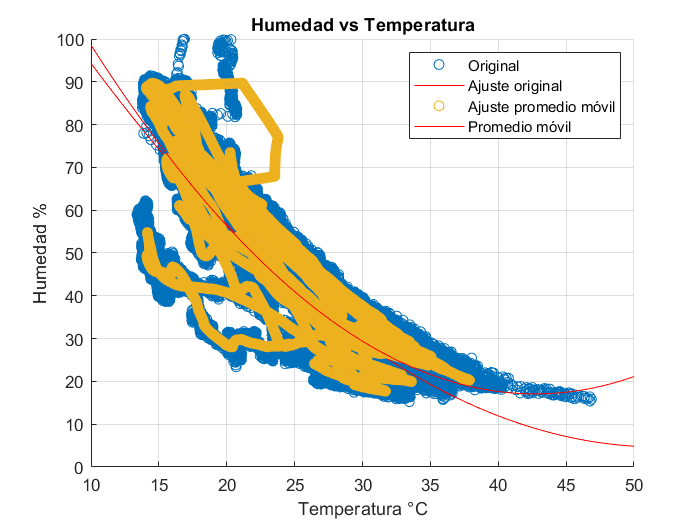


hold off

% Etiquetamos y demás
xlim([10 50])
ylim([0 100])
xlabel("Temperatura °C")
ylabel("Humedad %")
title("Humedad vs Temperatura")
legend("Original","Ajuste original", "Ajuste promedio móvil", "Promedio móvil")
grid on

**Conclusión:** El promedio móvil no fue bueno para quitar las variaciones en la gráfica de dispersión de humedad contra temperatura.